# RawEMG2EMG

## 0. Visualize Raw Data

clc;
clear;
load('./RawData/RawEMG.mat');

% Display data information
FsEMG = Fs;
tEMG = time;
clear Fs;
clear time;
fprintf('Data loaded successfully:\n');

Data loaded successfully:


fprintf('- Sampling frequency: %d Hz\n', FsEMG);

- Sampling frequency: 2500 Hz


fprintf('- Signal length: %.2f seconds\n', length(L_mass)/FsEMG);

- Signal length: 82.40 seconds


fprintf('- Number of samples: %d\n', length(L_mass));

- Number of samples: 205992


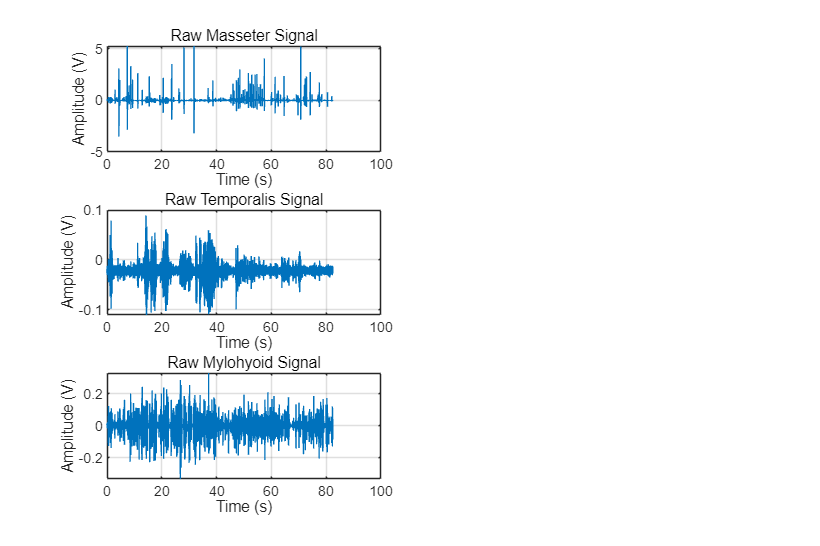


figure('Position', [100, 100, 1200, 800]);
subplot(3,2,1);
plot(tEMG, L_mass);
title('Raw Masseter Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(3,2,3);
plot(tEMG, L_temp);
title('Raw Temporalis Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(3,2,5);
plot(tEMG, L_mylo);
title('Raw Mylohyoid Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;


function [signal_filtered, emg_envelope] = preprocess_emg_us(emg_signal, FsEMG)
% This function preprocesses raw EMG signal recorded in a 60Hz environment.
% It includes DC removal, notch filter, band-pass filter, rectification, and envelope detection.
%
% INPUTS:
% emg_signal - The raw EMG data vector (column or row vector)
% FsEMG - The sampling frequency of the signal
%
% OUTPUT:
% emg_envelope - The processed linear envelope of the EMG signal
%
% Processing steps:
% 1. DC offset removal
% 2. Notch filter (60 Hz powerline interference)
% 3. Band-pass filter (20-450 Hz for EMG frequency range)
% 4. Full-wave rectification
% 5. Envelope extraction via low-pass filtering

% Ensure signal is a column vector
if isrow(emg_signal)
    emg_signal = emg_signal';
end

% Check for valid inputs
if FsEMG <= 0
    error('Sampling frequency must be positive');
end
if length(emg_signal) < 100
    warning('Signal is very short, filtering may not be reliable');
end

% 1. DC Offset Removal
signal_detrended = detrend(emg_signal, 'constant');

% 2. Notch Filter (60 Hz)
f_notch = 60; % Powerline frequency (Hz)
wo = f_notch / (FsEMG/2); % Normalized frequency

% Check if notch frequency is valid
if wo >= 1
    warning('Notch frequency too high for given sampling rate. Skipping notch filter.');
    signal_notched = signal_detrended;
else
    % Manual notch filter implementation (alternative to iirnotch)
    % Design a 2nd-order IIR notch filter
    r = 0.95; % Pole radius (closer to 1 = narrower notch)
    
    % Calculate filter coefficients
    b_notch = [1, -2*cos(pi*wo), 1];
    a_notch = [1, -2*r*cos(pi*wo), r^2];
    
    % Apply the notch filter
    signal_notched = filtfilt(b_notch, a_notch, signal_detrended);
end

% 3. Band-pass Filter (20-450 Hz)
f_low = 20; % Low cutoff (Hz) - removes motion artifacts
f_high = 450; % High cutoff (Hz) - matches your specification
order_band = 4; % 4th-order Butterworth filter

% Normalize frequencies
wn = [f_low, f_high] / (FsEMG/2);

% Check if frequencies are valid
if any(wn >= 1)
    error('Cutoff frequencies must be less than Nyquist frequency (%.1f Hz)', FsEMG/2);
end

[b_band, a_band] = butter(order_band, wn, 'bandpass');
signal_filtered = filtfilt(b_band, a_band, signal_notched);

% 4. Full-wave Rectification
signal_rectified = abs(signal_filtered);

% 5. Envelope Extraction (Low-pass Filter at 6 Hz)
f_cutoff_envelope = 6; % Envelope cutoff frequency (Hz)
order_envelope = 4; % 4th-order Butterworth filter

% Normalize frequency
wn_env = f_cutoff_envelope / (FsEMG/2);

if wn_env >= 1
    error('Envelope cutoff frequency too high for given sampling rate');
end

[b_low, a_low] = butter(order_envelope, wn_env, 'low');
emg_envelope = filtfilt(b_low, a_low, signal_rectified);

% Convert back to row vector if input was row vector
if isrow(emg_signal)
    emg_envelope = emg_envelope';
end

end

## Process Each Muscle Signal

fprintf('\nProcessing EMG signals...\n');


Processing EMG signals...



try
    [masseter_filtered, masseter_envelope] = preprocess_emg_us(L_mass, FsEMG);
    fprintf('✓ Masseter processed successfully\n');
catch ME
    fprintf('✗ Error processing Masseter: %s\n', ME.message);
    % Assign empty arrays to each variable separately
    masseter_filtered = [];
    masseter_envelope = [];
end

✓ Masseter processed successfully



try
    [temporalis_filtered, temporalis_envelope] = preprocess_emg_us(L_temp, FsEMG);
    fprintf('✓ Temporalis processed successfully\n');
catch ME
    fprintf('✗ Error processing Temporalis: %s\n', ME.message);
    temporalis_filtered = [];
    temporalis_envelope = [];
end

✓ Temporalis processed successfully



try
    [mylohyoid_filtered, mylohyoid_envelope] = preprocess_emg_us(L_mylo, FsEMG);
    fprintf('✓ Mylohyoid processed successfully\n');
catch ME
    fprintf('✗ Error processing Mylohyoid: %s\n', ME.message);
    mylohyoid_filtered = [];
    mylohyoid_envelope = [];
end

✓ Mylohyoid processed successfully


## Visualize Processed Results

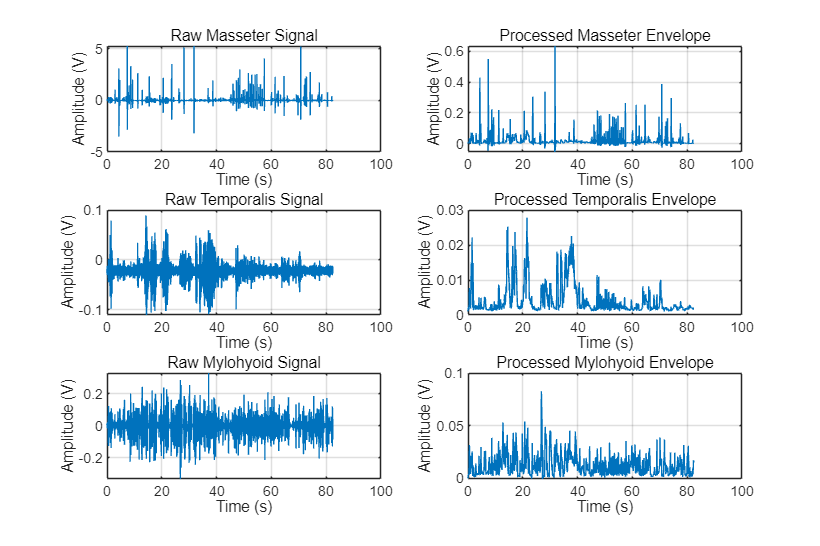

if ~isempty(masseter_envelope)
    subplot(3,2,2);
    plot(tEMG, masseter_envelope);
    title('Processed Masseter Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

if ~isempty(temporalis_envelope)
    subplot(3,2,4);
    plot(tEMG, temporalis_envelope);
    title('Processed Temporalis Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

if ~isempty(mylohyoid_envelope)
    subplot(3,2,6);
    plot(tEMG, mylohyoid_envelope);
    title('Processed Mylohyoid Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

## Save Results

fprintf('\nSaving processed data...\n');


Saving processed data...


save('./ProcessedData/EMG.mat', 'masseter_filtered', 'masseter_envelope', ...
    'temporalis_filtered', 'temporalis_envelope', ...
    'mylohyoid_filtered', 'mylohyoid_envelope', ...
    'tEMG', 'FsEMG');
fprintf('✓ Data saved to EMG.mat\n');

✓ Data saved to EMG.mat


## Optional: Display Signal Statistics

fprintf('\nSignal Statistics:\n');


Signal Statistics:


if ~isempty(masseter_envelope)
    fprintf('Masseter - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(masseter_envelope), std(masseter_envelope), max(masseter_envelope));
end

Masseter - Mean: 0.0225 V, Std: 0.0457 V, Max: 0.6341 V


if ~isempty(temporalis_envelope)
    fprintf('Temporalis - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(temporalis_envelope), std(temporalis_envelope), max(temporalis_envelope));
end

Temporalis - Mean: 0.0044 V, Std: 0.0045 V, Max: 0.0278 V


if ~isempty(mylohyoid_envelope)
    fprintf('Mylohyoid - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(mylohyoid_envelope), std(mylohyoid_envelope), max(mylohyoid_envelope));
end

Mylohyoid - Mean: 0.0122 V, Std: 0.0100 V, Max: 0.0827 V
